Exercise:

verify which among the following affine subspace are mutually parallel. Display with MATLAB the subspaces and their direction space.

Exercise

Σ1 : x - 2*y + 1 = 0*

*Σ2 : x - 2*

y + 3 = 0

Σ3 : 2*x + y + 1 = 0

Σ4 : x - y + 1 = 0

P=[2;1;2] + 

x-y=0

P=[1;0;0] + \rho[1;-1;0]

x-y+z+1=0

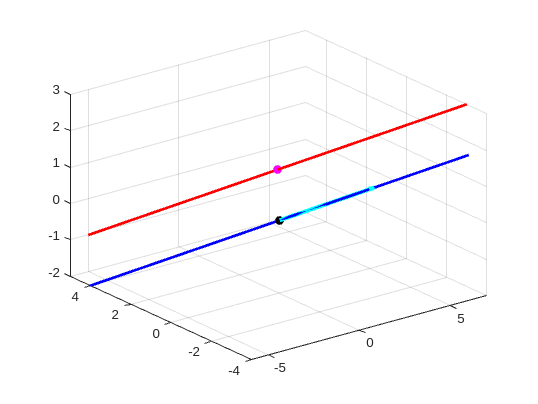

syms a real
u=[3 -2 1]'; V=a*u; %V is the direction space
P0=[1 1 1]'; S=P0+V; %S is the geometric space 
fplot3(S(1),S(2),S(3),[-2 2],'Color','r','LineWidth',2)
hold on
fplot3(V(1),V(2),V(3),[-2 2],'Color','b','LineWidth',2)
plot3(0,0,0,'ok','MarkerFaceColor','k')
plot3(P0(1),P0(2),P0(3),'om','MarkerFaceColor','m') %P0
quiver3(0,0,0,u(1),u(2),u(3),1,'Color','c','LineWidth',3) %u vector

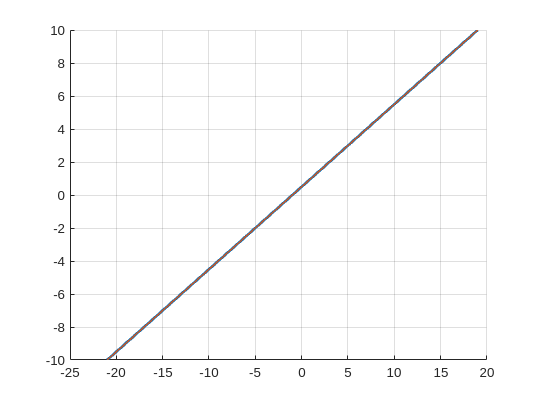

clf;

syms x y real;
d = [2; 1];
origin = [-1; 0];
t=linspace(-10,10,100);
x_vals=origin(1)+d(1)*t;
y_vals=origin(2)+d(2)*t;

hold on;
plot(x_vals, y_vals, 'LineWidth', 2); %Plot the direction space
grid on;
y_vals=t;
x_vals=2*y_vals-1;
plot(x_vals,t,'LineWidth',1); %plot the affine space
grid on; hold off;

clf;

clf;
A1=[1,-2]

A1 =      1    -2


syms x y real;
u=[x,y]

$$u = \left(\begin{array}{cc} x & y \end{array}\right)$$

b1=[-1]

b1 = -1

hold on; grid on;
Au=A1*u'

$$Au = x-2\,y$$

solve(A1*u'==b)

$$ans = 2\,y-1$$

fplot(solve(A*u'==b1),'LineWidth',7,'LineStyle','-.','Color','r')

A2=[1,-2]

A2 =      1    -2


b2=[-3]

b2 = -3

Au2=A2*u'

$$Au2 = x-2\,y$$

solve(Au2)

$$ans = 2\,y$$

fplot(solve(Au2==b2),'LineWidth',5,'LineStyle','--','Color','g')


A3=[2,1]

A3 =      2     1


b3=[-1]

b3 = -1

Au3=A3*u'

$$Au3 = 2\,x+y$$

solve(Au3)

$$ans = -\frac{y}{2}$$

fplot(solve(Au3==b3),'LineWidth',3,'LineStyle','--','Color','b')

A4=[1,-1]; b4=[-1] %x-y+1=0

b4 = -1

Au4=A4*u'

$$Au4 = x-y$$

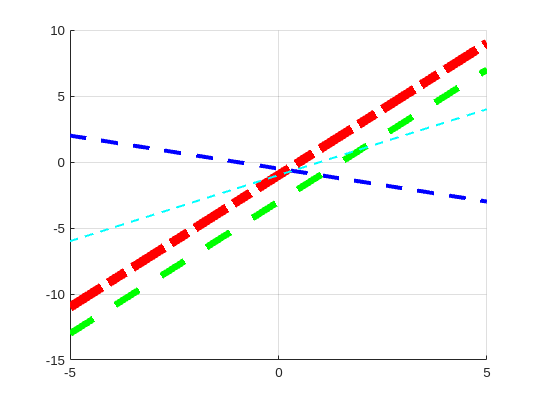

fplot(solve(Au4==b4),'LineWidth',1.5,'LineStyle','--','Color','c')
hold off;

P=[2;1;2] + $\rho[1;-1;0]$

x-y=0

P=[1;0;0] + $\rho[1;-1;0]$

x-y+z+1=0

clf; hold on; grid on;
syms x y z lambda real;
u=[x y z];
P1=[2;1;2]; u1=[1;-1;0]

u1 =      1
    -1
     0


S1=P1+lambda*u1

$$S1 = \left(\begin{array}{c} \lambda +2\\ 1-\lambda \\ 2 \end{array}\right)$$

fplot3(S1(1),S1(2),S1(3))
A2=[1,-1,0]; b2=[0]%x-y=0%

b2 = 0

Au2=A2*u';
%fplot(solve(Au2==0),'LineWidth',7,'LineStyle','--')
fsurf(s,'LineWidth',1)



P3=[1;0;0]; u3=[1;-1;0]

u3 =      1
    -1
     0


S2=P3+lambda*u3

$$S2 = \left(\begin{array}{c} \lambda +1\\ -\lambda \\ 0 \end{array}\right)$$

A4=[1,1,1]; b4=[-1] % x+y+z=-1

b4 = -1

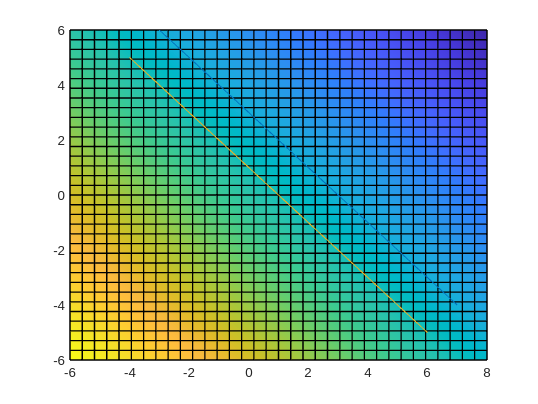

fplot3(S2(1),S2(2),S2(3))
Au4=A4*u';
s=solve(Au4==b4,x);
fsurf(s,'LineWidth',1)